# Prácticas de Control por Computador (3º GIERM, UMA)

## Práctica 5: Diseño de controladores PID en Matlab

#### **Tarea 1: Análisis respuesta temporal de control P, PI**

La gráfica muestra un sistema compuesto por un *proceso* a controlar usando un controlador digital, mediante la realimentación proporcionada por un *sensor digital*.

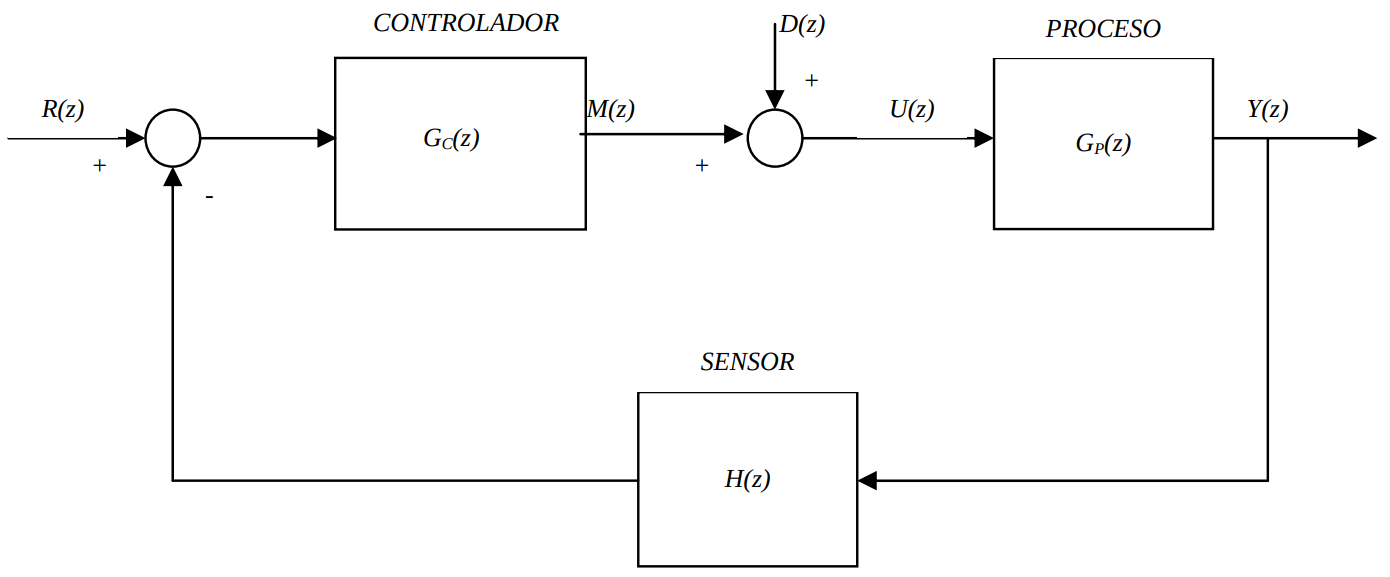

Si las funciones de transferencia del proceso continuo y el sensor continuo originales son $G_p \left(s\right)=\frac{4}{\left(2s+1\right)\left(0\ldotp 5s+1\right)}$ y $H\left(s\right)=\frac{1}{0\ldotp 05s+1}$ y el tiempo de muestreo es de $T=0\ldotp 1s$.

 **a.** Obtener graficamente la respuesta en bucle abierto $G_p \left(z\right)H\left(z\right)$del sistema, ante una entrada en escalón, discretizando la planta y sensor con el metodo 'zoh' (suponer que se realiza un muestreo entre el proceso y el sensor). ¿Qué valores toman el tiempo de subida $T_r$, el tiempo de establecimiento $T_s$, el valor en estado estacionario $Y_{\textrm{ss}}$y el maximo impulso porcentual $M_p$? (usar `step` y `stepinfo`).

% Tu código aquí
s = tf('s');
Gp = (4)/((2*s+1)*(0.5*s+1))

Gp =
 
         4
  ---------------
  s^2 + 2.5 s + 1
 
Continuous-time transfer function.
Model Properties


H = (1)/(0.05*s+1)

H =
 
      1
  ----------
  0.05 s + 1
 
Continuous-time transfer function.
Model Properties


T = 0.1;
Gpd = c2d(Gp,T,'zoh');
Hd = c2d(H,T,'zoh');
Plant = Gpd*Hd

Plant =
 
         0.01592 z + 0.01465
  ----------------------------------
  z^3 - 1.905 z^2 + 1.018 z - 0.1054
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


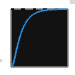

ans = struct with fields:
         RiseTime: 4.6000
    TransientTime: 8.6000
     SettlingTime: 8.6000
      SettlingMin: 3.6007
      SettlingMax: 3.9980
        Overshoot: 0
       Undershoot: 0
             Peak: 3.9980
         PeakTime: 15.9000


figure
step(Plant); stepinfo(Plant)

`Resultado esperado:`

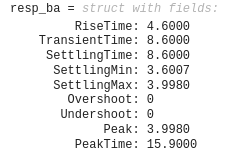

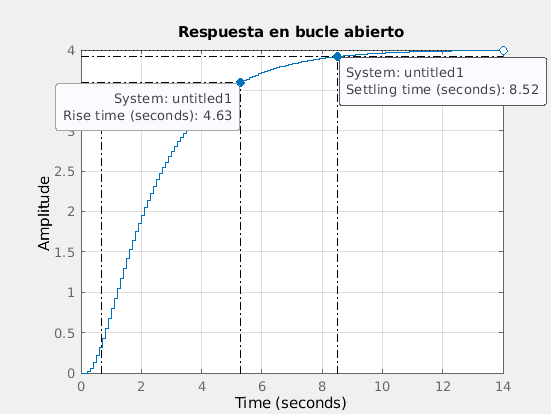

 **b.** Diseñar un controlador P digital, con valores $K_p$=0.7, 1.2 y 1.7. Obtener todas las gráficas del sistema con el controlador, ante una entrada escalón, en una misma representación gráfica evaluando el tiempo de subida $T_r$, el tiempo de establecimiento $T_s$, el error en estado estacionario $E_{\textrm{ss}}$y el maximo impulso porcentual $M_p$. ¿Qué cambios se observan conforme aumenta $K_p$, en los cuatro parámetros analizados anteriormente?.

% Tu código aquí
Kp1 = 0.7;
Kp2 = 1.2;
Kp3 = 1.7;
figure
Gd1 = feedback(Kp1*Gpd,Hd)

Gd1 =
 
  0.01289 z^2 + 0.01012 z - 0.001605
  -----------------------------------
  z^3 - 1.905 z^2 + 1.029 z - 0.09514
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


stepinfo(Gd1)

ans = struct with fields:
         RiseTime: 0.9000
    TransientTime: 4.2000
     SettlingTime: 4.2000
      SettlingMin: 0.6992
      SettlingMax: 0.8495
        Overshoot: 15.2876
       Undershoot: 0
             Peak: 0.8495
         PeakTime: 1.9000


Gd2 = feedback(Kp2*Gpd,Hd)

Gd2 =
 
   0.0221 z^2 + 0.01734 z - 0.002752
  -----------------------------------
  z^3 - 1.905 z^2 + 1.037 z - 0.08782
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


stepinfo(Gd2)

ans = struct with fields:
         RiseTime: 0.5000
    TransientTime: 4.8000
     SettlingTime: 4.8000
      SettlingMin: 0.7462
      SettlingMax: 1.0863
        Overshoot: 31.2600
       Undershoot: 0
             Peak: 1.0863
         PeakTime: 1.4000


Gd3 = feedback(Kp3*Gpd,Hd)

Gd3 =
 
  0.03131 z^2 + 0.02457 z - 0.003899
  -----------------------------------
  z^3 - 1.905 z^2 + 1.045 z - 0.08049
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


stepinfo(Gd3)

ans = struct with fields:
         RiseTime: 0.5000
    TransientTime: 5.4000
     SettlingTime: 5.4000
      SettlingMin: 0.6905
      SettlingMax: 1.2704
        Overshoot: 45.7226
       Undershoot: 0
             Peak: 1.2704
         PeakTime: 1.2000


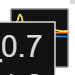

figure
step(Gd1,Gd2,Gd3)
legend('Gd1 Kp = 0.7','Gd2 Kp = 1.2','Gd3 Kp = 1.7')

`Resultado esperado:`

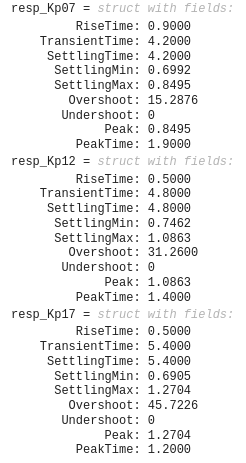

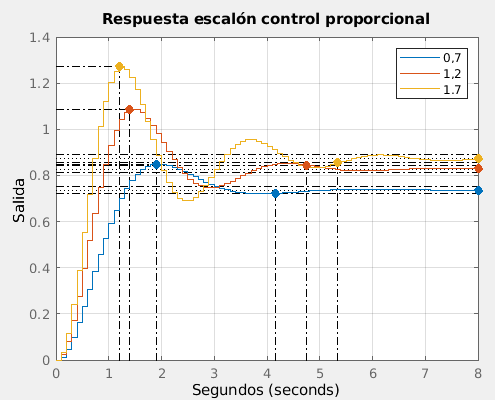

 **c.** Sustituir el controlador P digital por un controlador PI digital, obtenido a partir de la discretización trapezoidal del PI continuo, con un valor fijo de $K_p =1\ldotp 7$y $K_i$tomando valores 0.25 y 0.5. Obtener todas las gráficas de las respuesta del sistema con el controlador, ante una entrada escalón. ¿Qué cambios se observan ahora, conforme aumenta  $K_i$, en los parámetros?.

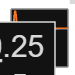

% Tu código aquí
Kp = 1.7;
Ki1= 0.25;
Ki2 = 0.5;

Gpid1 = pid(Kp,Ki1,0,0,T,'IFormula','Trapezoidal'); %avisa de que le voy a decir que voy a meterle un metodo de integracion y Trapezoidal es el metodo
Gpid2 = pid(Kp,Ki2,0,0,T,'IFormula','Trapezoidal');
figure
hold on
step(feedback(Gpid1*Gpd,Hd))
step(feedback(Gpid2*Gpd,Hd))
legend('Ki = 0.25','Ki = 0.5')
hold off

`Resultado esperado:`

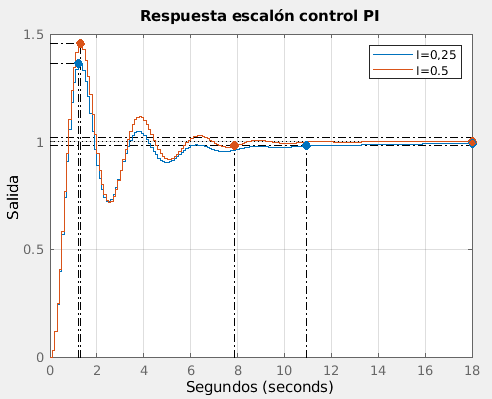

#### Tarea 2: Analisis de control PID

El sistema de control de la figura muestra un control de velocidad PID (proporcional + integral + derivativo) que actia sobre un motor de corriente contínua, con función de transferencia


$$G_p \left(s\right)=\frac{0\ldotp 01}{0\ldotp 005s^2 +0\ldotp 06s+0\ldotp 1001}$$


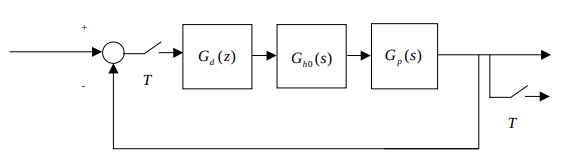

El controlador PID viene dado por


$$G_d \left(s\right)=K_p +\frac{K_i }{s}+K_d s=\frac{K_d s^2 +K_p s+K_i }{s}$$


con valores variables de $K_p$, $K_i$y$K_d$.

Representar gráficamente de forma simultanea la respuesta escalón en bucle cerrado del sistema de control con el PID discretizado:

- Con $K_p$=50, $K_i =K_d =0$.

- Con $K_p$=50, $K_i$=20 y $K_d =0$.

- Con $K_p$=50, $K_i$=20 y $K_d =5$.

aplicando el metodo de discretización trapezoidal (transformacion bilineal) para el PID, con un tiempo de muestreo $T$=0.01.

% Tu código aquí
Gp = tf([0.001],[0.005 0.06 0.1001])

Gp =
 
             0.001
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.
Model Properties


T = 0.01;
Gpd = c2d(Gp,T,'zoh')

Gpd =
 
  9.61e-06 z + 9.233e-06
  ----------------------
  z^2 - 1.885 z + 0.8869
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


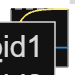

P = pid(50);
PI = pid(50,20);
PID = pid(50,20,5);
Gpid1z = pid(50,0,0,0,T,'Iformula','Trapezoidal','Dformula','Trapezoidal');
Gpid2z = pid(50,20,0,0,T,'Iformula','Trapezoidal','Dformula','Trapezoidal');
Gpid3z= c2d(PID,0.01,'tustin');
figure; hold on
step(feedback(Gp*P,1))
step(feedback(Gp*PI,1))
step(feedback(Gp*PID,1))
legend('Gpid1','Gpid2','Gpid3');
hold off

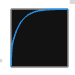

figure
step(feedback(Gpd*Gpid3z,1))

`Resultado esperado:`

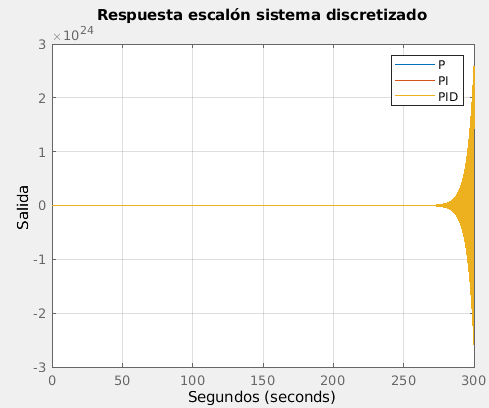

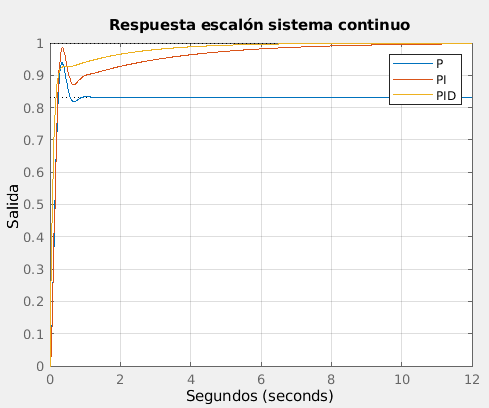

#### Tarea 3: Diseño de compensador PID en tiempo discreto

Considerese el sistema definido por su función de transferencia:


$$G\left(s\right)=\frac{1}{s^2 +18s+90}$$


compensada en tiempo discreto con una ganancia *K* variable.

**a.** Discretizar el sistema con *T*=0.1 y trazar el lugar de las raices del sistema contínuo original y del sistema discretizado y compararlo.

% Tu código aquí


`Resultado esperado:`

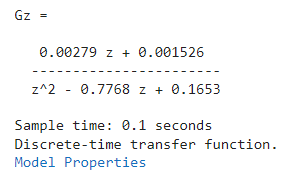

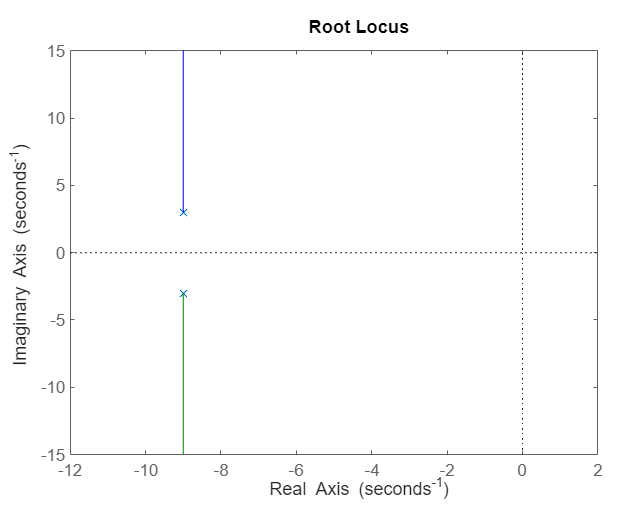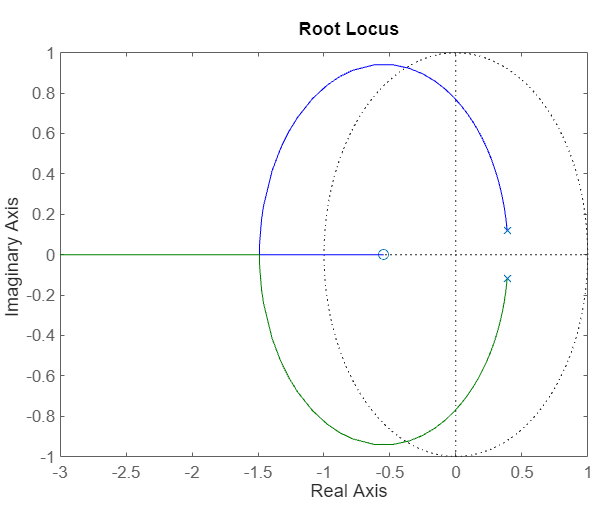

**b.** Hallar mediante el lugar de las raices discreto con rltool, el valor de *K* para que el sistema en bucle cerrado en tiempo discreto presente un sobreoscilación máxima porcentual$M_p$ inferior al 5%, un tiempo de establecimiento menor de 1s y con error en régimen permanente mínimo ante una entrada tipo escalón.

% Tu código aquí


`Resultado esperado:`

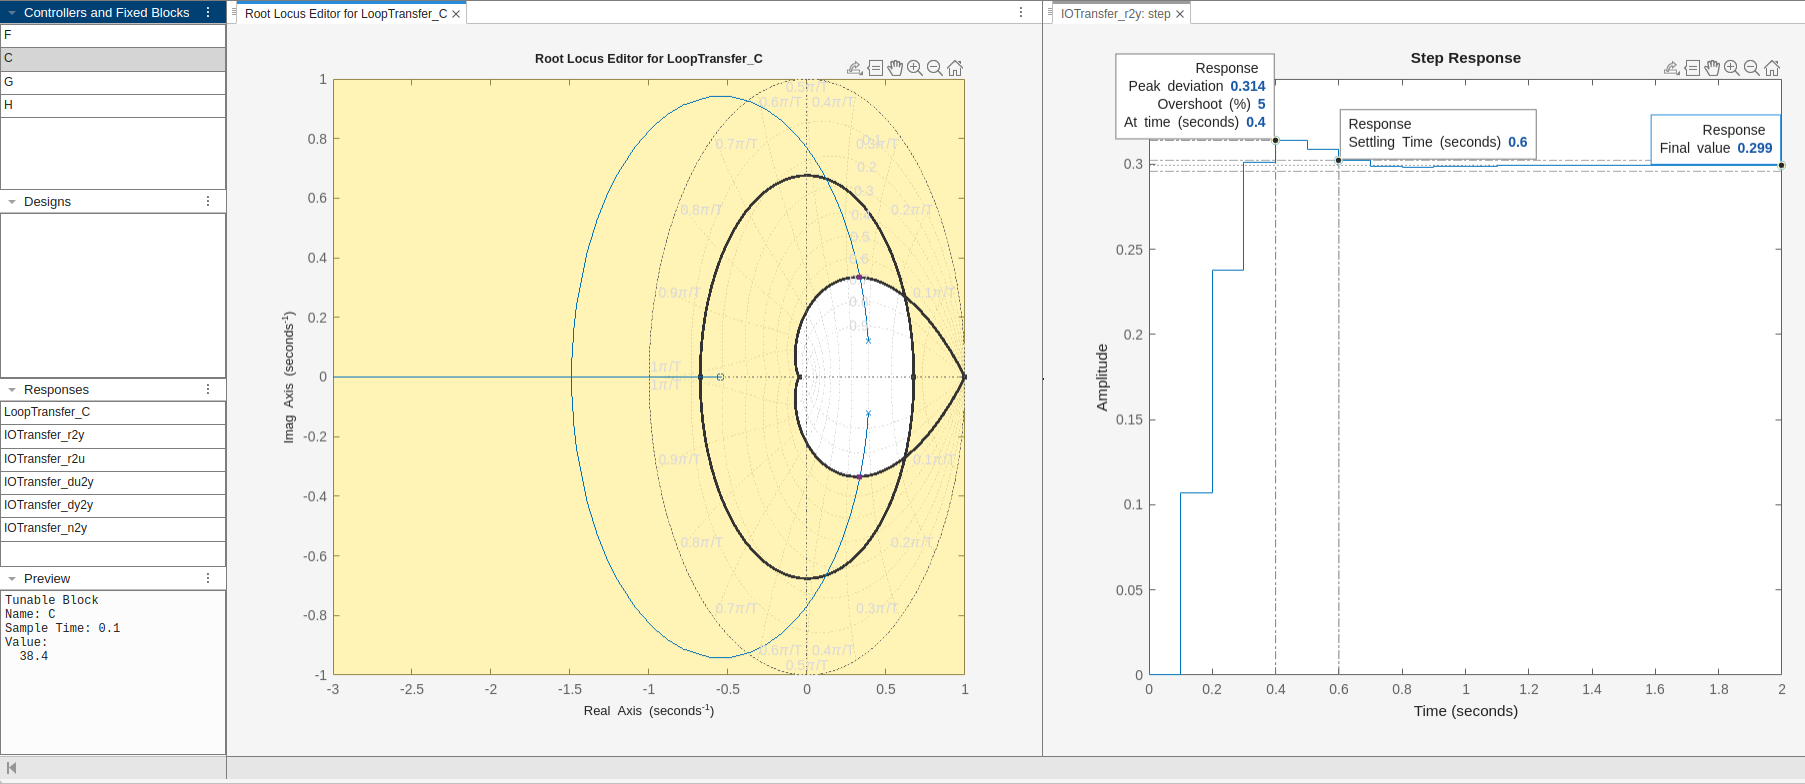

**c.**  Hallar directamente en el plano z un compensador digital tipo PI, PD o PID para que el sistema en bucle cerrado en tiempo discreto presente una sobreoscilación máxima $M_p$ inferior al 5%, un tiempo de establecimiento menor de 1s y con error de segumiento para una entrada escalón nulo. Razonar la solución.

% Tu código aquí


`Resultado esperado:`